disp('problema 1')

problema 1


disp('rezultat Lagrange')

rezultat Lagrange


Lagrange([0 1 2], [exp(0) exp(1) exp(2)], 0.25) 

ans = 1.1528


disp('rezultat Hermite')

rezultat Hermite


Hermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], 0.25)

ans = 1.2500

disp('rezultat e^0.25')

rezultat e^0.25


exp(0.25)

ans = 1.2840

pp2:

x1 = [0.3 0.32 0.35];
y1 = [0.29552 0.31457 0.34290];
derivata1 = [0.95534 0.94924 0.93937];
disp('inainte de 0.33:')

inainte de 0.33:


Hermite(x1, y1, derivata1, 0.34)

ans = 0.3337



x = [0.3 0.32 0.33 0.35];
y = [0.29552 0.31457 0.3240 0.34290];
derivata = [0.95534 0.94924 0.9460 0.93937];
disp('dupa 0.33:')

dupa 0.33:


Hermite(x, y, derivata, 0.34)

ans = 0.3337

disp('sin34:')

sin34:


sin(0.34)

ans = 0.3335

pp3:

timp = [0 3 5 8 13];
distanta = [0 225 383 623 993];
viteza = [75 77 80 74 72];
t=10;
disp('Distanta parcursa la momentul t=10')

Distanta parcursa la momentul t=10


d = Hermite(timp, distanta, viteza, t)

d = 750

disp('Viteza la momentul t=10')

Viteza la momentul t=10


disp(d/t)

    75




d = Hermite(distanta, viteza, timp, d)

d = 75

% nu e ok d / t, iau functia de viteza, derivata acceleratia

Pr1:

disp('problema 1:')

problema 1:


x = [1 1.5 2];
y = [exp(1) exp(1.5) exp(2)];
yd = [exp(1) exp(1.5) exp(2)];
Hermite(x, y, yd, 1.2)

ans = 3.2619

exp(1.2)

ans = 3.3201

Pr2:

disp('problema 2:')

problema 2:


nodes = [1.1 1.2 1.7 1.8 3];
nodevals = exp(nodes);

t = 1 : 0.1 : 3

t =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


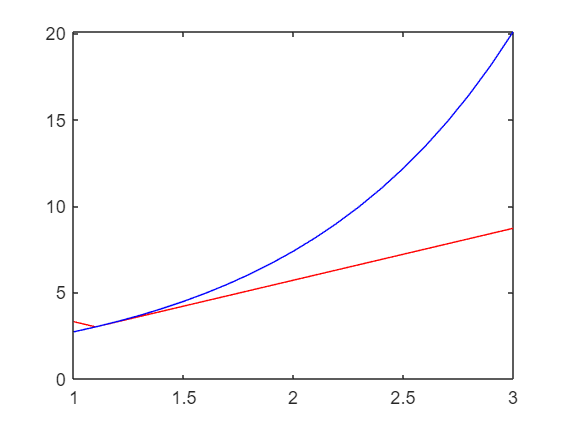

res = HermiteMaiMultePuncte(nodes, nodevals, nodevals, t);
plot(t, res, 'r');
hold on;
resexp = exp(t);
plot(t, resexp, 'b');
hold off;

Pr3:

disp('problema 3:')

problema 3:


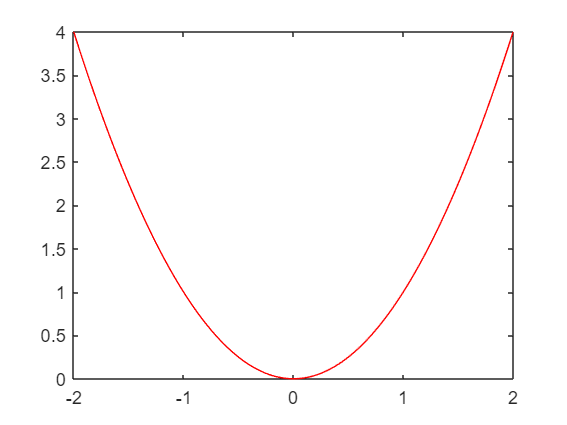

% Fie f: [-2, 2] -> R, f(x) = x^2
x = [-2 2];
f = [4 4]; 
fderiv = [-4 4];

t = -2 : 0.01 : 2;
results = HermiteMaiMultePuncte(x, f, fderiv, t);
plot(t, results, 'red');